# Dynamic Model of Two Wheel Self Balancing Robot

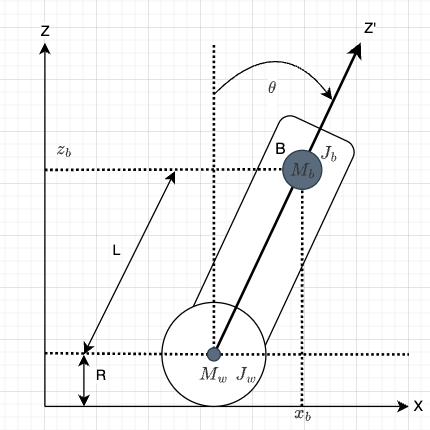

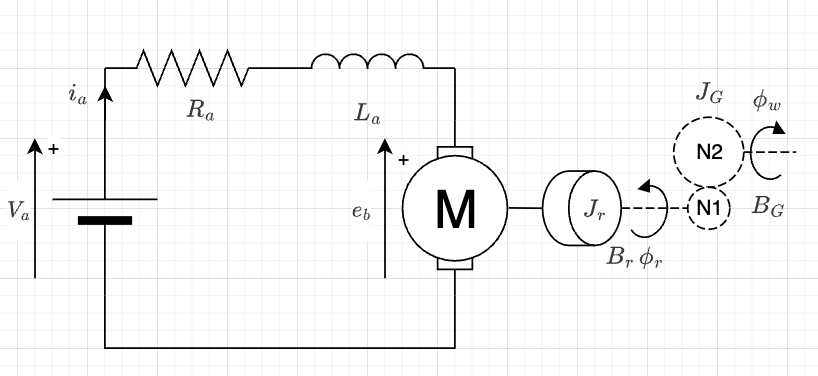

Steady State


$$\textrm{atan2}\left(-a_x ,a_z \right)$$


$n=\frac{N_2 }{N_1 }$ Gear Teet ratio

$T_m \left(t\right)=K_t \cdot i_a \left(t\right)\;$ torque generate by motor rotor

$J_r \cdot {\ddot{\phi} }_r +B_r \cdot {\dot{\phi} }_r =K_t \cdot i_a \left(t\right)\;$ mechancial torque balance equation

$V_a \left(t\right)=i_a \left(t\right)\cdot R_a +e_b \left(t\right)$ kcl 


$$e_b \left(t\right)=K_e \cdot {\dot{\phi} }_r \;$$
 

$\Omega_w \left(s\right)=\frac{{s\cdot \phi }_r \left(s\right)}{n}$ output shaft speed is less than inpu

$T_w \left(s\right)=n\cdot T_m \left(s\right)-s\cdot B_G \cdot \phi_w$  gearbox  increases torque

$J_{\textrm{eq}} =J_G +n^2 \cdot J_r$ and $B_{\textrm{eq}} =B_G +n^2 \cdot B_r$

Full Transfer Function DC Motor


$$\frac{\Omega_w \left(s\right)}{V_a \left(s\right)}=\frac{K_t }{s^2 \cdot L_a R_a +\;s\left(R_a \cdot J_{\textrm{eq}} +B_{\textrm{eq}} \cdot L_a \right)+K_t {\cdot K}_e +R_a \cdot B_{\textrm{eq}} }\cdot \frac{1}{n}$$
 

Reduced order similification for small DC motros with low electical time constant 


$$\frac{\Omega_w \left(s\right)}{V_a \left(s\right)}=\frac{K_t }{\;s\left(R_a \cdot J_{\mathrm{eq}} \right)+K_t {\cdot K}_e +R_a \cdot B_{\mathrm{eq}} }\cdot \frac{1}{n}$$
 

clear
Jr = 3.2284E-5;   % rotor rotational inertia        [Nms^2/rad]
Jg = 3.22E-5;     % Gearbox Rotational Inertia
Bg = 0.0001;      % vicous friction           [Nms/rad]
Br = 0;

% DC Motor Manufacturuer Parameters 
IStall = 2;
TStall = 0.39;
Inoload = 0.2;
n = 20;
%Identified parameters
speedvolt_grad = 0.6594*n*2*pi; % Measumenents in RPS of output shaft

Kt = ((IStall - Inoload)/ TStall) ^-1;         % Motor Torque constant        []
Ke = (speedvolt_grad)^-1 ;        % Motor Back EMF constant speed voltage gradient      []
Ra = 2.6;         % armature resistance       [Ω]
La = 1E-6;        % armature inductance          [H]
n = 20;
Jeq = Jg + n^2*Jr;
Beq = Bg + n^2*Br;


s = tf("s"); 
motor_tf = (Kt*n^-1)/((s^2)*(La*Ra) + s*(Ra*Jeq + Beq *La) + Kt*Ke + Ra*Beq)


motor_tf =
 
               0.01083
  ----------------------------------
  2.6e-06 s^2 + 0.03366 s + 0.002875
 
Continuous-time transfer function.
Model Properties


motor_simp_tf = (Kt*n^-1)/ (s*(Ra*Jeq) + Kt*Ke + Ra*Beq)


motor_simp_tf =
 
        0.01083
  --------------------
  0.03366 s + 0.002875
 
Continuous-time transfer function.
Model Properties




 
step(motor_simp_tf ); ylabel('rads');grid on; grid minor;  
hold on; step(motor_tf); s  hold off; legend("Simplified","Full Order");


tf1ct =
 
  From input "u1" to output "y1":
    35.74
  ---------
  s + 25.12
 
Name: tf1ct
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "step". 
Fit to estimation data: 92.2% (stability enforced)
FPE: 0.08197, MSE: 0.08171                        
 
Model Properties
